%计算考虑化学作用后的双腔室二锁体系
clear all
syms e r o;

y1=[];
y2=[];
Plock=[];
Vlock=[];
Vopen=[];

%笼腔长度等于多少个sigma(o)
l=2.5;



%计算锁死所占成分
    fun1 = @(x1) P(x1).^3.*P(l-x1).^2;
    V_lock = 2*integral(fun1,0,l);

%计算开放所占成分
    fun2 = @(x1) P(x1-l).^2.*P(2*l-x1);
    V_open = 2*integral(fun2,l,2*l);
    P_lock = V_lock/(V_lock + V_open)  %计算锁死所占比例

P_lock = 0.9925

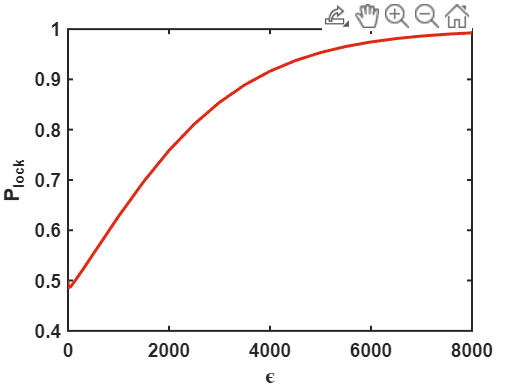

  



%画出锁死概率随l的变化
e=[0 10 50 100 300 500 1000 ...
    1500 2000 2500 3000 3500 4000 ...
    4500 5000 5500 6000 6500 7000 ...
    7500 8000];
Plock=[0.5 0.4854 0.4878 0.4939 0.5227 0.5529 0.6275 ... 
    0.6970 0.7586 0.8111 0.8544 0.8891 0.9163 ...
    0.9373 0.9533 0.9654 0.9744 0.9811 0.9861 ...
    0.9898 0.9925];
plot(e, Plock,'LineWidth',1.5, ...
    'color',[221, 42, 22]/256)


set(gca,'linewidth',1,'FontWeight','bold','FontName','arial');
xlabel('\epsilon','FontName','arial','FontWeight','bold'); 
ylabel('P_{lock}','FontName','arial','FontWeight','bold');

function a= E(r) %定义特定的势能函数E(r)
    e=8000;
    o=1;%计算的其实是o/r
    a=4.*e.*(((r/o).^(-12))-((r/o).^(-6)));
end

function b=P(r) %定义相应的概率分布函数P(r)
    b=exp(-E(r)/(8.31*298));
end

